# Phys 434 Lab 6

## Natalie Shen

### Collaborators: Taylor Prewitt, Francesca Bennet

clear all; close all; clc

h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');

h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

## Problem 1

The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]

% data = higg(2,:);
% histogram(data);
% m = mean(data);

%probability for sigma 5 is 1 out of 3.5 million
s5p=1/(3.5 * 10.^6);

%value for sigma 5
s5v = icdf("poisson",1-s5p,100)

s5v = 154

## Problem 2

Now create a set of injected (simulated) signals of a *single strength*. You will want to make your signal moderately strong, say somewhere in the 8-30σ range. Inject this signal into your background data many times.

### a)

 Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.

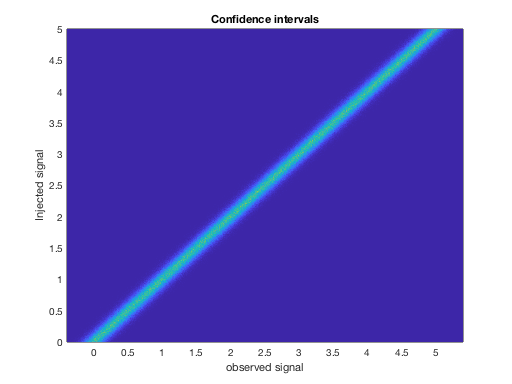

size = 1000;
n = randn(size,size)*0.1;
ss = linspace(0,5,1000);
[in, signal] = meshgrid(ss);
obvs = n + signal;

figure()
h = histogram2(obvs,signal,1000,'DisplayStyle','tile','ShowEmptyBins','on');
grid on
ylabel("Injected signal")
xlabel("observed signal")
title("Confidence intervals")

%grid on

figure()
index = 250;
signal(index)

ans = 1.2462

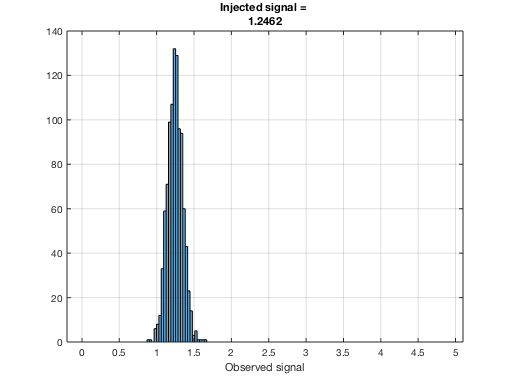



histogram(obvs(index,:),25)
grid on
xlim([-0.2 5.1])
title(["Injected signal = ", num2str(signal(index))])
xlabel("Observed signal")

### b)

Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?

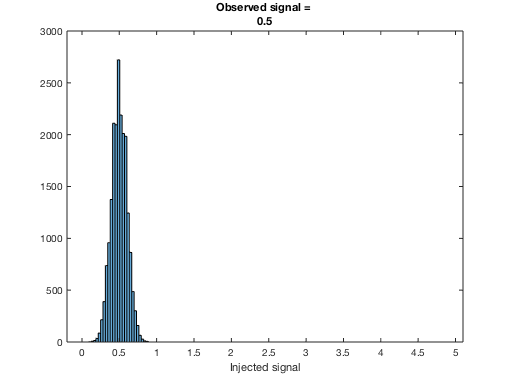

observation = .5;

injected = signal(abs(obvs - observation)<0.05);
histogram(injected,25)
xlim([-0.2 5.1])
title(["Observed signal = ", num2str(observation)])
xlabel("Injected signal")

## Problem 3

Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). 

### a)

Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal

### b)

If you choose the same injected signal power as in problem 2, show that you get the same answer.

### c)

Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.

### d)

Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.

### e)

Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?

## Problem 4

Using the same setup as in problem 3, now pick a relatively weak signal (say in the 1σ range, exact strength not important).

### a)

Repeat problem 3c, calculating the injected signal pdf(). One of the differences you should immediately see is that the pdf() extends to zero.

### b)

 Describe what it means to have the true signal pdf() extend to zero.

### c)

Calculate a 95% confidence upper bound. [Hints: make sure your pdf() is normalized. The statistical question is:  if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than *X* 95% of the time.]